ADAM (Adaptive Moment Estimation - Adaptivní odhad momentu) je, přesně jak název napovídá, adaptivní změna momentu během výpočtu. Moment se odhaduje dle vzorečků viz: 

file:///C:/Users/vojte/OneDrive%20-%20Z%C3%A1pado%C4%8Desk%C3%A1%20univerzita%20v%20Plzni/PhD/Courses/Metody%20strojov%C3%A9ho%20u%C4%8Den%C3%AD%20v%20elektrotechnice/Schuzka_Smidl_25_10_2021/Gradientn%C3%AD%20metody.pdf#page=4&zoom=100,165,932

Nagenerujeme data pomocí funkce. V tomto případě se jedná o fnunkci:

#### 
$$y_{\left(x\right)} =\cos \left(2\left(x-1\right)+3\right)$$
 

func = @(x) cos((x-1).*2+3); % funkce pro nagenerování dat                
from = -pi;                  % rozsah pro od ...
to = pi;                     % ... do pro nagenerování dat
N = 20;                         % počet vzorků
x = from:((to-from)/(N-1)):to;  % vzorkovací čas            
y = awgn(func(x),20);           % generátor naměřených dat skrze funkci pro nagenerování dat (prostě přidá do funkce šum)    

Klasicky navolíme maximální chybu výpočtu a koeficinet učení.

alpha = 0.5;      % míra učení
tau = 0.01;       % maximální možná chyba pro ukončení výpočtu
syms q_sym;

Zde je vytvořena bázová funkce. Ta má tvar:

#### 
$$y_{\left(x\right)} =\cos \left(\textrm{qx}+\frac{q}{2}\right)$$


Tato bázová funkce nikdy úplně kvalitně neaproximuje nagenerovaná data, ale vytvoří nám "pěknou" ztrátovou funkci pro vysvětlení momentu.

y_a = cos(q_sym.*x)+0.5.*q_sym; % zde je provedno vytvořrní bázové funkce

Následně je vytvořena ztrátová funkce pomocí metody nejmenších čtverců:

E_sym = sum((y - y_a).^2);

A ta je poté derivována podle parametru $q$.

dE_sym = diff(E_sym,q_sym);

"Náhodný" výchozí bod je zde zvolen -3.

q = -3;

Hodnota $\beta_1 ,\beta_2 ,\varepsilon$ jsou konstanty ycházející z materiálu viz výše.

epsilon = 10e-8;
beta1 = 0.9;
beta2 = 0.999;

Tyto dvě proměné jsou příprava pro průběžné výpočty.

m = 0;
v = 0;

A nyní už samotný výpočet. Po výpočtu derivace ztrátové funkce je postupováno dle vzorečků viz materiál.

dE = 0;
for i = 1:1000 

    dE = (double(subs(dE_sym,q_sym,q)));
    
    m = beta1*m+(1-beta1)*dE;
    v = beta2*v+(1-beta2)*dE^2;
 
    mm = m/(1-beta1^i);
    vv = v/(1-beta2^i);
    
    if abs(dE) < tau
        break;
    end
    
    q = q - ((alpha*mm)/(sqrt(vv)+epsilon));
end

Vypsání zjištěných koeficientů

q

q = -0.5365

Vykreslení naměřených dat.

plot(x,y,"ro");
hold on;

Vykreslení aproximace vypočteným modelem.

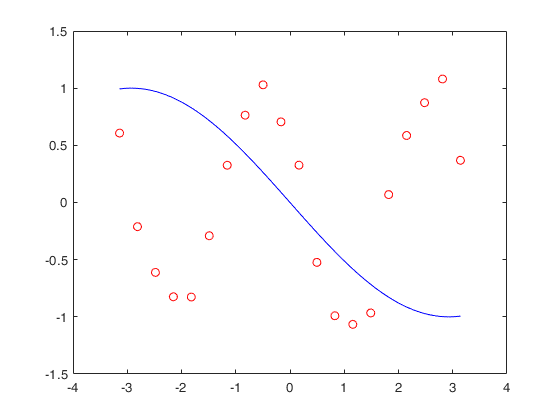

plot(from:((to-from)/(N*10-1)):to,sin((from:((to-from)/(N*10-1)):to).*q),"b-");
hold off;

Vykreslení ztrátové funkce. Můžeme si povšimnout, že ani zde se výpočet nezastavil v lokálnímu minimu, jako tomu bylo u klasické metody BGD bez použití momentu. Metoda je navíc velmi rychlá.

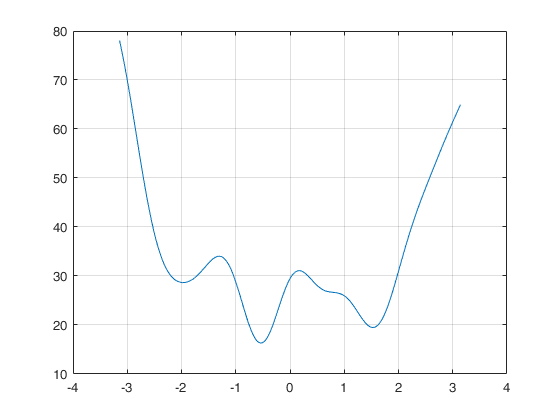

plot(from:((to-from)/(N*10-1)):to,double(subs(E_sym,q_sym,from:((to-from)/(N*10-1)):to)));
grid on;

Vykreslení derivace ztrátové funkce.

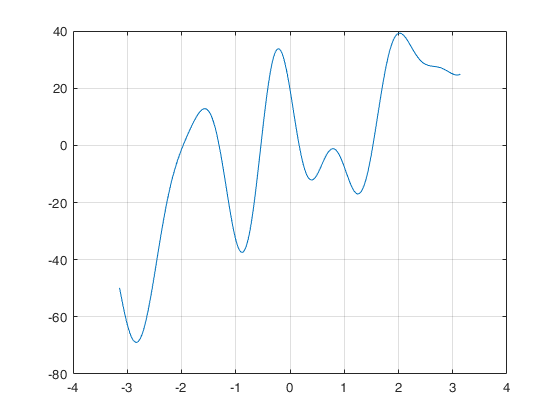

plot(from:((to-from)/(N*10-1)):to,double(subs(dE_sym,q_sym,from:((to-from)/(N*10-1)):to)));
grid on;